# ARI - Homework 5		

% initialize
clear all
close all
clc

% useful commands
help tf 

 tf  Construct transfer function or convert to transfer function.
 
   Construction:
     SYS = tf(NUM,DEN) creates a continuous-time transfer function SYS with
     numerator NUM and denominator DEN. SYS is an object of type tf when
     NUM,DEN are numeric arrays, of type GENSS when NUM,DEN depend on tunable
     parameters (see REALP and GENMAT), and of type USS when NUM,DEN are
     uncertain (requires Robust Control Toolbox).
 
     SYS = tf(NUM,DEN,TS) creates a discrete-time transfer function with
     sample time TS (set TS=-1 if the sample time is undetermined).
 
     S = tf('s') specifies the transfer function H(s) = s (Laplace variable).
     Z = tf('z',TS) specifies H(z) = z with sample time TS.
     You can then specify transfer functions directly as expressions in S
     or Z, for example,
        s = tf('s');  H = exp(-s)*(s+1)/(s^2+3*s+1)
 
     SYS = tf

help feedback

 feedback  Feedback connection of two input/output systems. 
 
    M = feedback(M1,M2) computes a closed-loop model M for the feedback loop: 
 
           u --->O---->[ M1 ]----+---> y
                 |               |           y = M * u
                 +-----[ M2 ]<---+
 
    Negative feedback is assumed and the model M maps u to y. To apply 
    positive feedback, use the syntax M = feedback(M1,M2,+1).
 
    M = feedback(M1,M2,FEEDIN,FEEDOUT,SIGN) builds the more general feedback 
    interconnection:
 
                       +------+
           v --------->|      |--------> z
                       |  M1  |
           u --->O---->|      |----+---> y
                 |     +------+    |
                 |                 |
                 +-----[  M2  ]<---+
 
    The vector FEEDIN contains indices into the input vector of M1 and
    specifies which inputs u are involved in the feedback loop. Similarly, 
    FEED

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.




% type 'help' followed by the command to learn about that specific function
% using the percent sign allows comments in MATLAB
% to compile/run your livescript hit "run" at the top of your screen

## Tasks 	

*Please answer the following in the spaces provided below, justify your conclustion:	*

#### Assignment 1 – Feedback							

Compare the two systems shown below: 

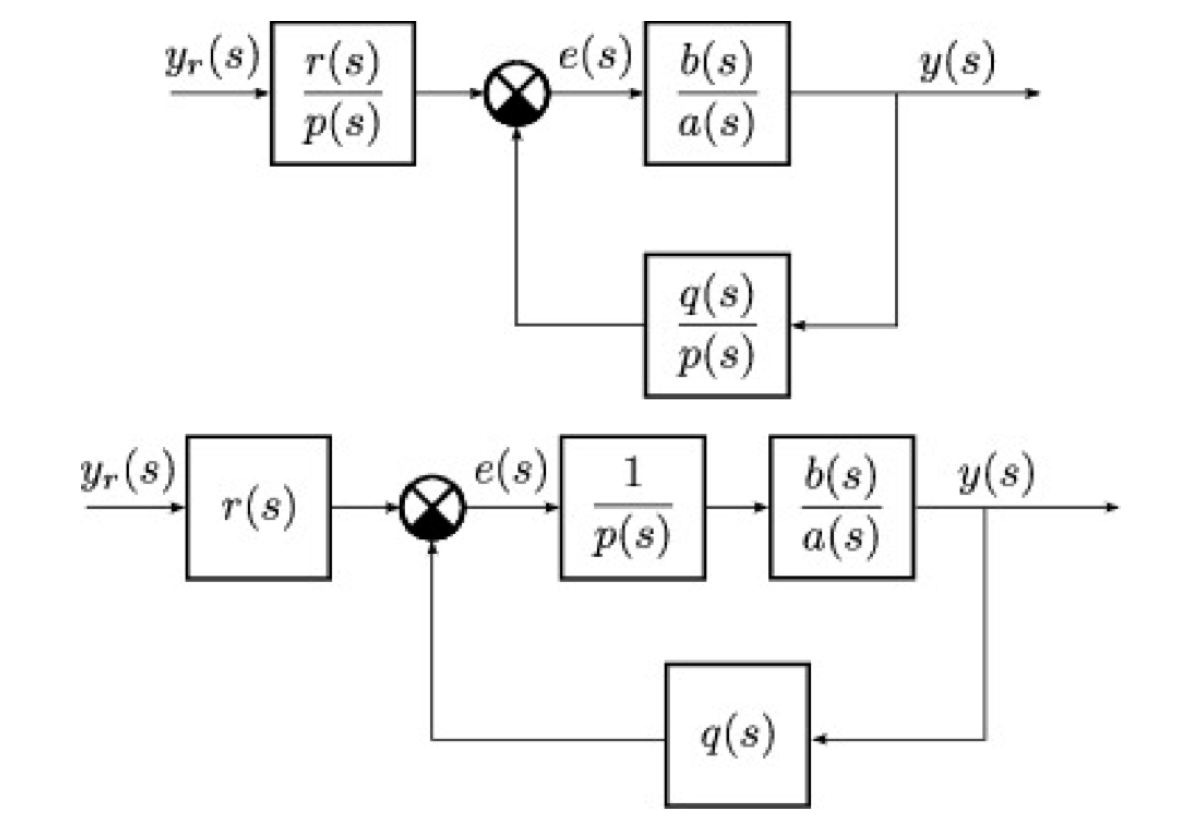			

- Find out, what is their difference in terms of stability. Hint: determine internal stability conditions of each of the system and compare these conditions. Explain the difference. 				

 % insert your code here	

#### Assignment 2 – Feedforward								

The response of the system $P\left(s\right)$is affected by a disturbance. The transfer function $P\left(s\right)=P_1 \left(s\right)P_2 \left(s\right)$is given by 


$$P_1 \left(s\right)=\frac{s+2}{s+1},P_2 \left(s\right)=\frac{1}{s-1}$$
	 

The disturbance enters the system in the middle – between $P_1 \left(s\right)$and $P_2 \left(s\right)$, as shown in the following figure:	 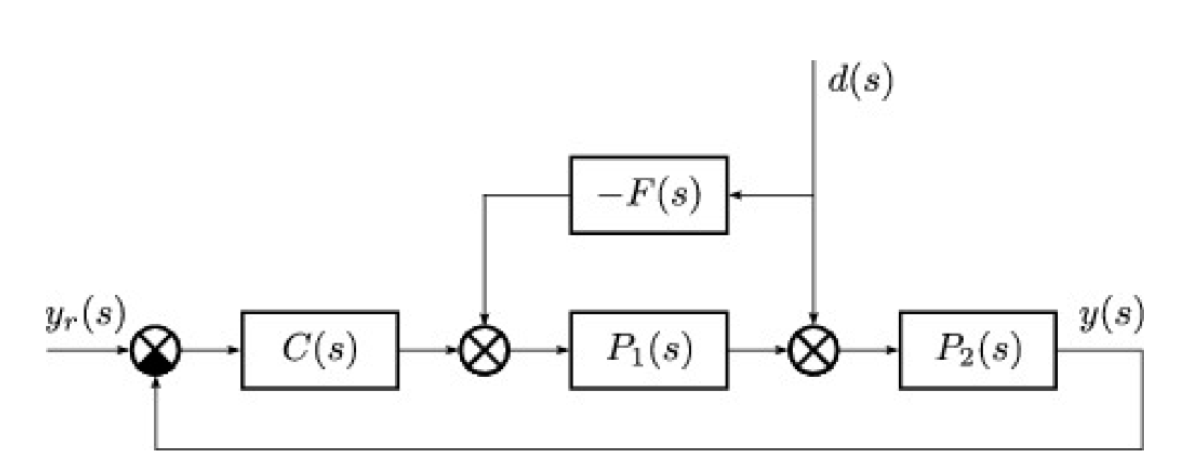This disturbance is measurable before it enters the plant $P_2 \left(s\right)$. The control input is at the input of the system $P_1 \left(s\right)$. 

- Design both the feedforward compensator $F\left(s\right)$ and the feedback controller $C\left(s\right)$ such that the closed- loop system is stable and the effect of the disturbance on the output $y$ is minimized. **Hint:** First calculate the transfer function from the disturbance to the output. In this special case this transfer function can be easily transformed to zero by finding the compensator $F\left(s\right)$. Then design a feedback controller $C\left(s\right)$.  

% insert your code here	